%% System Parameters
N = 20;          % Number of quadrature nodes (for Gauss-Hermite integration)
SNR = 1;         % Signal-to-Noise Ratio
array = [2, 4, 8, 16, 32, 64, 128, 256];
% M = 16;          % Size of the PAM constellation (number of symbols)
d = 2;           % Distance parameter (spacing between constellation points)
R = 0.5;         % Communication rate

%% Compute Gauss-Hermite Nodes and Weights
% These are used for numerical integration over a Gaussian density.
[nodes, weights] = GaussHermite_Locations_Weights(N);

total_times_old = zeros(4, length(array));
total_times_new = zeros(4, length(array));

for i = 1:length(array)

    M = array(i);

    %% Generate and Normalize PAM Constellation
    % Create a PAM constellation with M symbols and spacing d.
    X = generatePAMConstellation(M, d);
    % Normalize the constellation so that its average energy is 1.
    X = X / sqrt(mean(X.^2));

    %% Initialize the Probability Distribution for Constellation Symbols
    % Create a column vector where each symbol has equal probability (1/M).
    Q = repmat(1/M, 1, M);
    Q = Q';

    %% Define the Gaussian Function
    G = @(z) exp(-abs(z).^2) / pi;

    %% Create Required Matrices for Computation
    pi_matrix = createPiMatrix(M, N, weights);
    z_matrix = createComplexNodesMatrix(nodes);
    g_matrix = createGMatrix(X, z_matrix, SNR, G);

    rho = 0.5;
    n = 1e2;
    T = zeros(1,4);
    T_old = zeros(1,4);

    for j = 1:n
        [m, mp, m2p, times_old] = F0_matrix(Q, pi_matrix, g_matrix, rho);
        [F0, dF0, d2F0, times_new] = derivativesE0(Q, pi_matrix, g_matrix, rho);
        T = T + times_new;
        T_old = T_old + times_old;

    end
    total_times_new(:, i) = T';
    total_times_old(:, i) = T_old';

    disp(M);
end

     2

     4

     8

    16

    32

    64

   128

   256




disp(total_times_old);

   0.005640666666667   0.007868833333333   0.018201500000000   0.050346666666667   0.233029625000000   0.739543166666666   2.621307541666666  11.228796249999997
   0.000215500000000   0.000281041666667   0.000714375000000   0.002436791666667   0.036763708333333   0.054826875000000   0.156000583333333   0.432586291666667
   0.000701500000000   0.001174000000000   0.003571500000000   0.011648916666667   0.104258541666667   0.222459500000000   0.644145000000000   2.720955375000000
   0.000981708333333   0.001741083333333   0.005158416666667   0.019646791666667   0.150874083333333   0.354106708333333   1.090277791666666   4.691688375000001



disp(total_times_new);

   0.005896916666667   0.008030708333333   0.017517708333333   0.047643958333333   0.242421666666667   0.659919000000000   2.400956583333334  10.446531333333333
   0.000222708333333   0.000297583333333   0.000766541666667   0.003261583333333   0.034226708333333   0.052300958333333   0.150028625000000   0.420676208333333
   0.000808750000000   0.001349541666667   0.003837500000000   0.017819333333333   0.135778791666667   0.383222916666667   1.205792833333333   5.714224958333332
   0.002947500000000   0.005729208333333   0.018071750000000   0.058456958333333   0.454743208333333   0.973278458333333   3.268894041666668  15.506051874999994



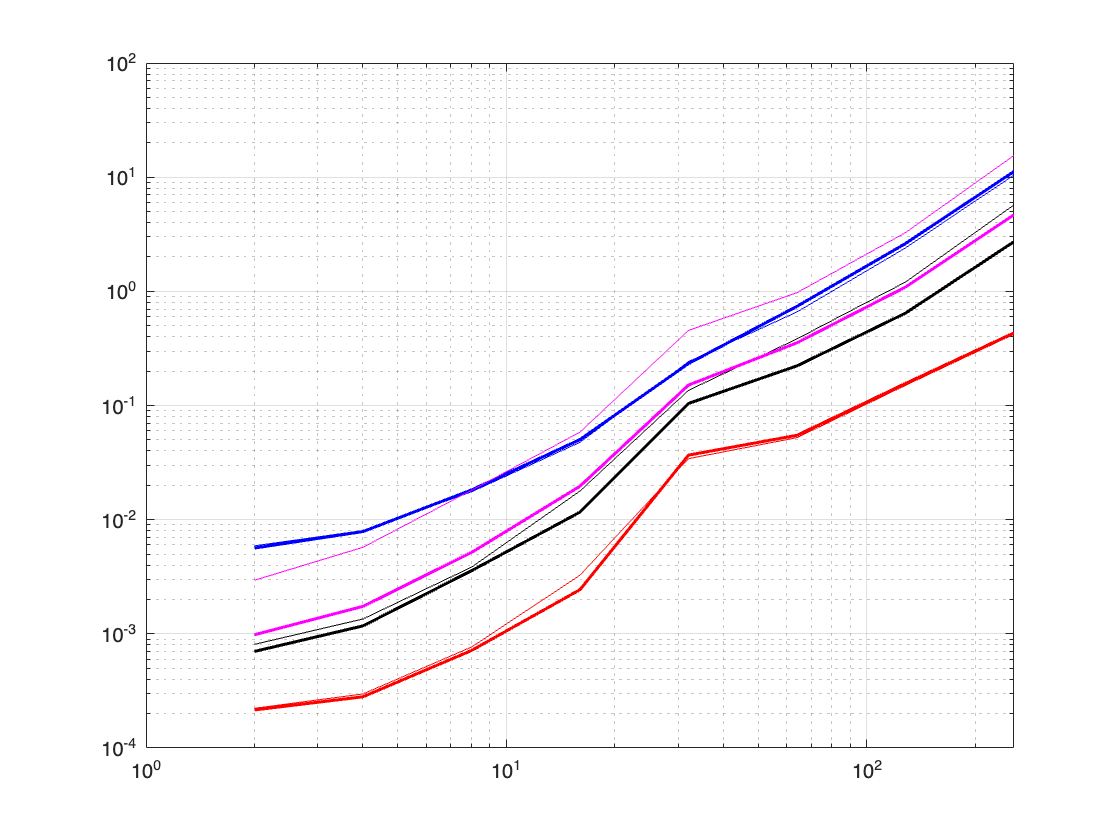



figure;
loglog(array, total_times_old(1,:),'Color', 'b', 'LineWidth', 1.5);
hold on;
loglog(array, total_times_new(1,:),'Color', 'b');

loglog(array, total_times_old(2,:),'Color', 'r', 'LineWidth', 1.5);
loglog(array, total_times_new(2,:),'Color', 'r');

loglog(array, total_times_old(3,:),'Color', 'k', 'LineWidth', 1.5);
loglog(array, total_times_new(3,:),'Color', 'k');

loglog(array, total_times_old(4,:),'Color', 'm', 'LineWidth', 1.5);
loglog(array, total_times_new(4,:),'Color', 'm');
grid on;
hold off;

%% System Parameters
Nset = 1:20;                                   % Quadrature nodes: 1, 2, ..., 20
M_array = [2, 4, 8, 16, 32, 64, 128, 256];     % PAM constellation sizes from 2 up to 1024
SNR = 1;                                       % Signal-to-Noise Ratio
d = 2;                                         % Distance parameter (spacing between constellation points)
R = 0.5;                                       % Communication rate (available if needed)

%% Preallocate arrays for execution times
numMetrics = 4;  % We assume 4 timing metrics are returned from your functions
total_times_old = zeros(numMetrics, length(M_array), length(Nset));
total_times_new = zeros(numMetrics, length(M_array), length(Nset));

nIter = 100;  % Number of iterations for averaging execution time

%% Main Simulation Loop
for idxN = 1:length(Nset)
    N = Nset(idxN);
    
    % Compute Gauss-Hermite Nodes and Weights for current N.
    % (Ensure your function handles N=1 gracefully.)
    [nodes, weights] = GaussHermite_Locations_Weights(N);
    
    % Compute the complex nodes matrix once per N (depends only on nodes)
    z_matrix = createComplexNodesMatrix(nodes);
    
    for idxM = 1:length(M_array)
        M = M_array(idxM);
        
        %% Generate and Normalize PAM Constellation
        X = generatePAMConstellation(M, d);
        X = X / sqrt(mean(X.^2));  % Normalize constellation to unit average energy
        
        %% Initialize the Probability Distribution for Constellation Symbols
        Q = repmat(1/M, M, 1);  % Uniform distribution for each symbol
        
        %% Define the Gaussian Function
        G = @(z) exp(-abs(z).^2) / pi;
        
        %% Create Required Matrices for Computation
        pi_matrix = createPiMatrix(M, N, weights);
        g_matrix = createGMatrix(X, z_matrix, SNR, G);
        
        rho = 0.5;
        T_new = zeros(1, numMetrics);
        T_old = zeros(1, numMetrics);
        
        %% Run simulation nIter times to average execution times
        for j = 1:nIter
            % The functions below are assumed to return 4 timing metrics in the 4th output.
            [~, ~, ~, times_old] = F0_matrix(Q, pi_matrix, g_matrix, rho);
            [~, ~, ~, times_new] = derivativesE0(Q, pi_matrix, g_matrix, rho);
            T_new = T_new + times_new;
            T_old = T_old + times_old;
        end
        
        % Store average execution times for this combination of M and N
        total_times_new(:, idxM, idxN) = T_new' / nIter;
        total_times_old(:, idxM, idxN) = T_old' / nIter;
        
        % Progress update
        disp(['Completed: M = ', num2str(M), ', N = ', num2str(N)]);
    end
end

Completed: M = 2, N = 1
Completed: M = 4, N = 1
Completed: M = 8, N = 1
Completed: M = 16, N = 1
Completed: M = 32, N = 1
Completed: M = 64, N = 1
Completed: M = 128, N = 1
Completed: M = 256, N = 1
Completed: M = 512, N = 1
Completed: M = 2, N = 2
Completed: M = 4, N = 2
Completed: M = 8, N = 2
Completed: M = 16, N = 2
Completed: M = 32, N = 2
Completed: M = 64, N = 2
Completed: M = 128, N = 2
Completed: M = 256, N = 2
Completed: M = 512, N = 2
Completed: M = 2, N = 3
Completed: M = 4, N = 3
Completed: M = 8, N = 3
Completed: M = 16, N = 3
Completed: M = 32, N = 3
Completed: M = 64, N = 3
Completed: M = 128, N = 3
Completed: M = 256, N = 3
Completed: M = 512, N = 3
Completed: M = 2, N = 4
Completed: M = 4, N = 4
Completed: M = 8, N = 4
Completed: M = 16, N = 4
Completed: M = 32, N = 4
Completed: M = 64, N = 4
Completed: M = 128, N = 4
Completed: M = 256, N = 4
Completed: M = 512, N = 4
Completed: M = 2, N = 5
Completed: M = 4, N = 5
Completed: M = 8, N = 5
Completed: M = 16, N = 5
Com


%% Display the Execution Time Arrays (if needed)
disp('Old Method Execution Times:');

Old Method Execution Times:


disp(total_times_old);


(:,:,1) =

   0.000006367500000   0.000000914166667   0.000001765416667   0.000004720416667   0.000020786666667   0.000043203333333   0.000103338333333   0.000304021250000   0.001869861666667
   0.000000147083333   0.000000136666667   0.000000149583333   0.000000161666667   0.000000304583333   0.000000872500000   0.000002716250000   0.000010302916667   0.000199054583333
   0.000002760833333   0.000000532500000   0.000000650833333   0.000000971250000   0.000001865000000   0.000006400000000   0.000019970416667   0.000080179166667   0.000697373750000
   0.000005021666667   0.000001113750000   0.000000960000000   0.000001088333333   0.000001703333333   0.000004895416667   0.000016636250000   0.000059083750000   0.000760970000000


(:,:,2) =

   0.000000882916667   0.000001641666667   0.000004971666667   0.000021837083333   0.000050779166667   0.000103595000000   0.000357543333333   0.001789727083333   0.004267598333333
   0.000000116250000   0.000000146250000   0.000000186250000   0.00000

disp('New Method Execution Times:');

New Method Execution Times:


disp(total_times_new);


(:,:,1) =

   0.000003434583333   0.000001046250000   0.000001643750000   0.000004690416667   0.000020886250000   0.000038303333333   0.000097013333333   0.000279505416667   0.001727252916667
   0.000000165416667   0.000000150000000   0.000000162083333   0.000000177083333   0.000000345000000   0.000001036250000   0.000002864583333   0.000010013333333   0.000202874166667
   0.000004747500000   0.000000683333333   0.000000834583333   0.000001120833333   0.000001788333333   0.000007663750000   0.000024197500000   0.000082985833333   0.001002778750000
   0.000013946666667   0.000001374583333   0.000001730000000   0.000002358333333   0.000004051250000   0.000020311250000   0.000060275416667   0.000213301666667   0.002219122083333


(:,:,2) =

   0.000000953333333   0.000001715833333   0.000004941666667   0.000022309166667   0.000049227916667   0.000097642083333   0.000335451250000   0.001666015416667   0.003877969583333
   0.000000138333333   0.000000170000000   0.000000202083333   0.00000

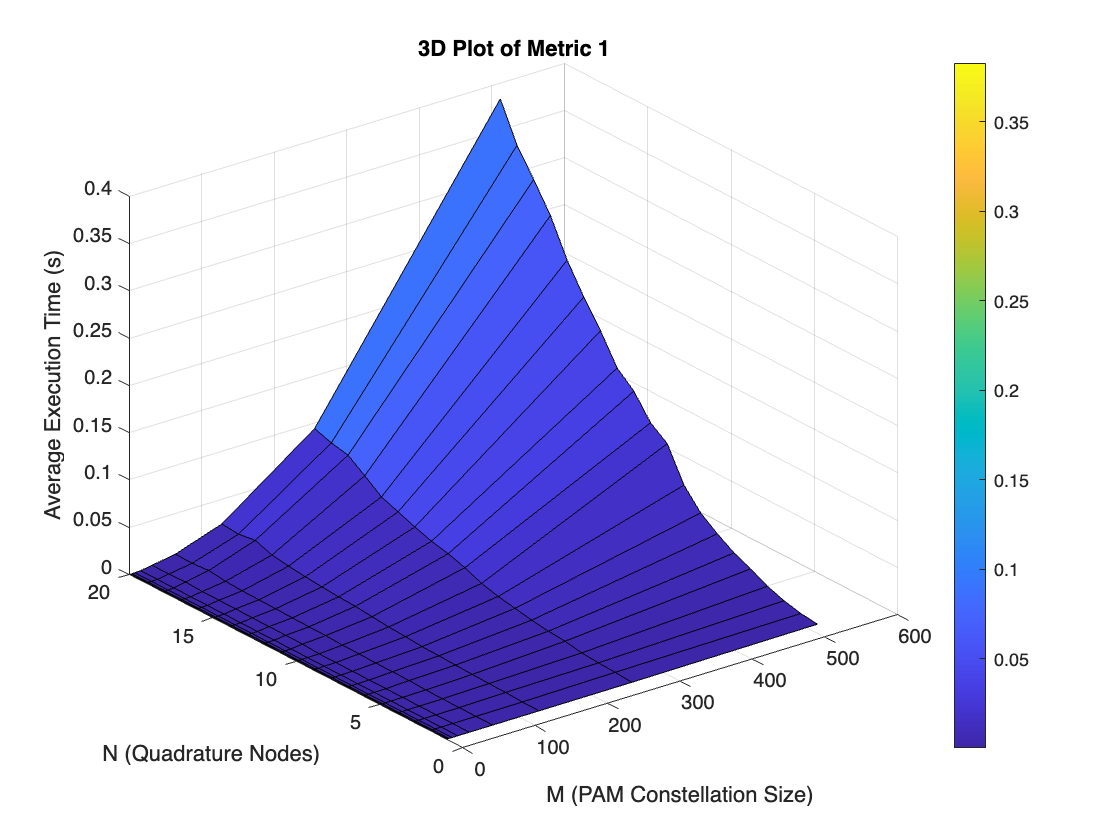

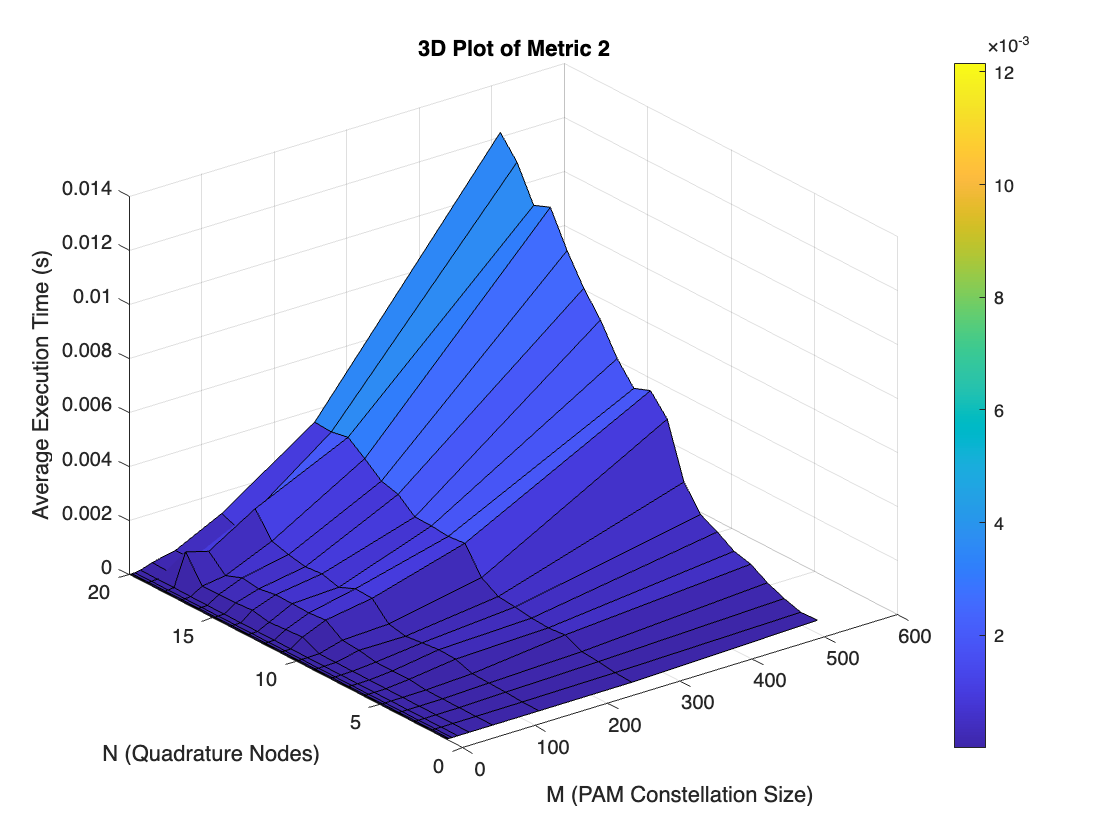

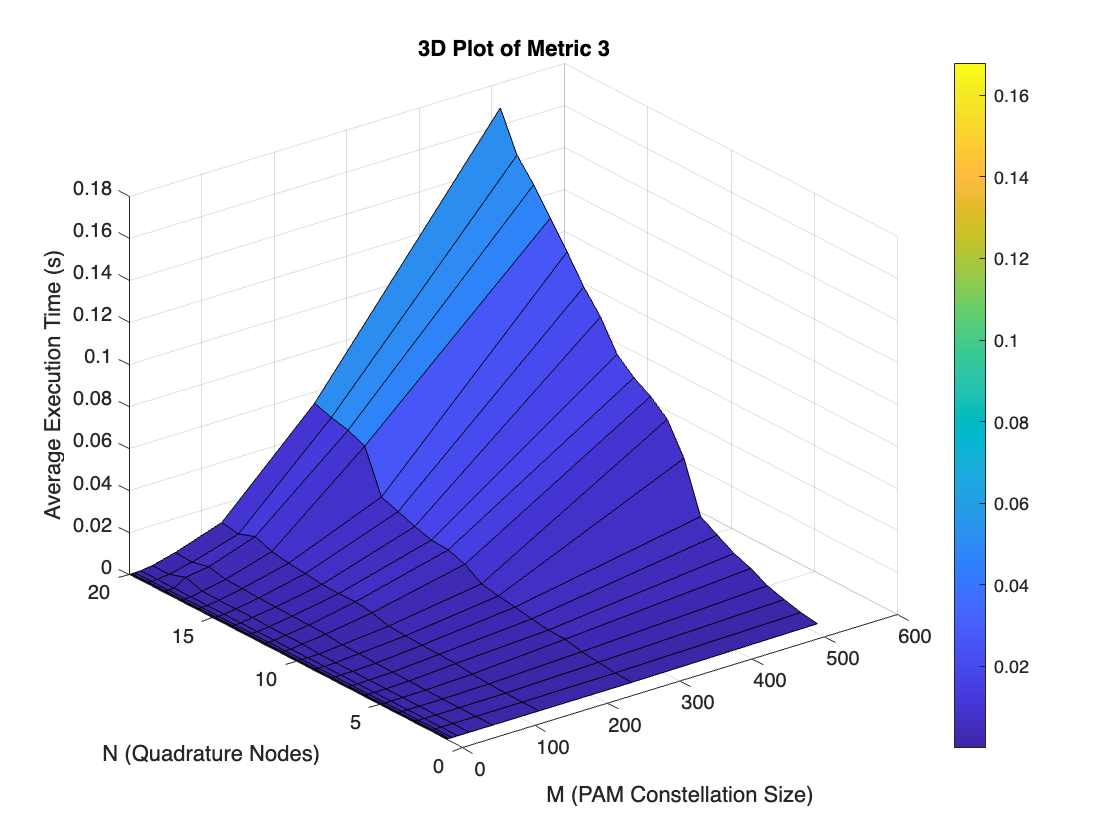

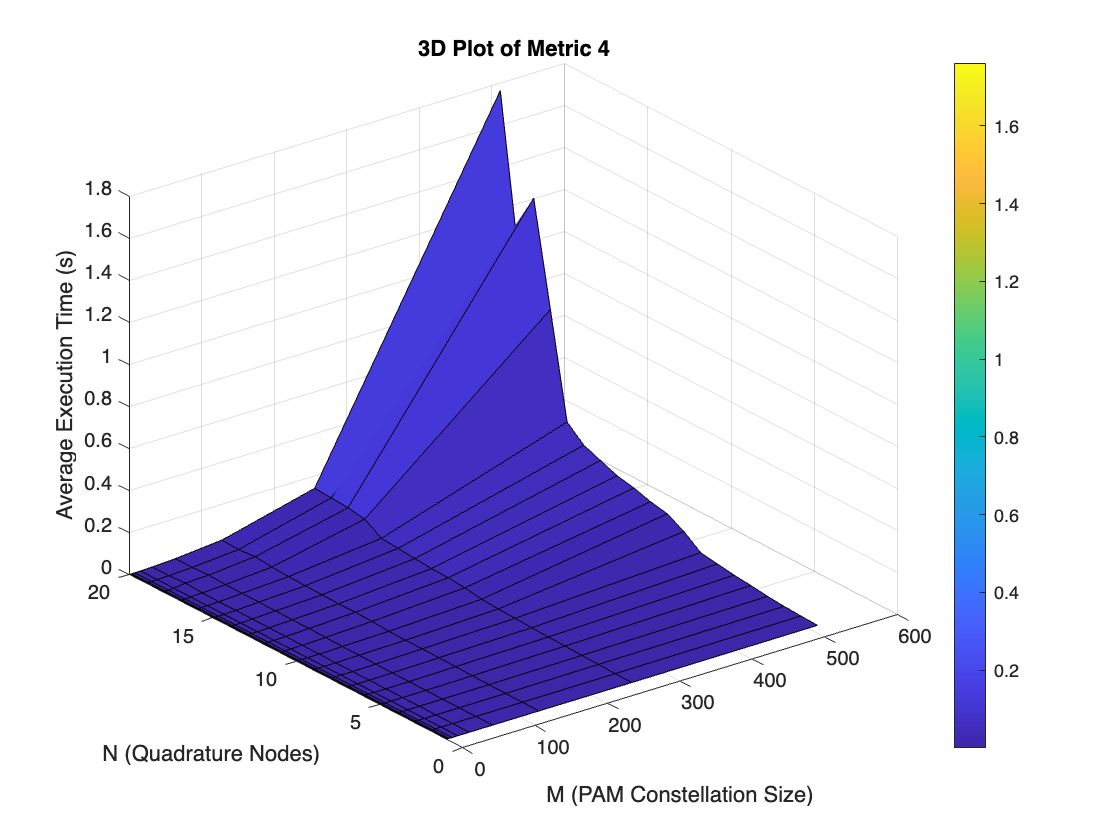


%% Create Meshgrid for Plotting
% Meshgrid for M (x-axis) and N (y-axis)
[M_grid, N_grid] = meshgrid(M_array, Nset);

%% 3D Surface Plots for the 4 Metrics (New Method)
for metric = 1:numMetrics
    % Extract the average execution times for the current metric.
    % squeeze converts from [1 x length(M_array) x length(Nset)] to [length(M_array) x length(Nset)].
    % Then, we transpose so that the first dimension corresponds to Nset.
    time_metric = squeeze(total_times_new(metric, :, :))';  

    figure;
    surf(M_grid, N_grid, time_metric);
    xlabel('M (PAM Constellation Size)');
    ylabel('N (Quadrature Nodes)');
    zlabel('Average Execution Time (s)');
    title(['3D Plot of Metric ', num2str(metric)]);
    colorbar;
end

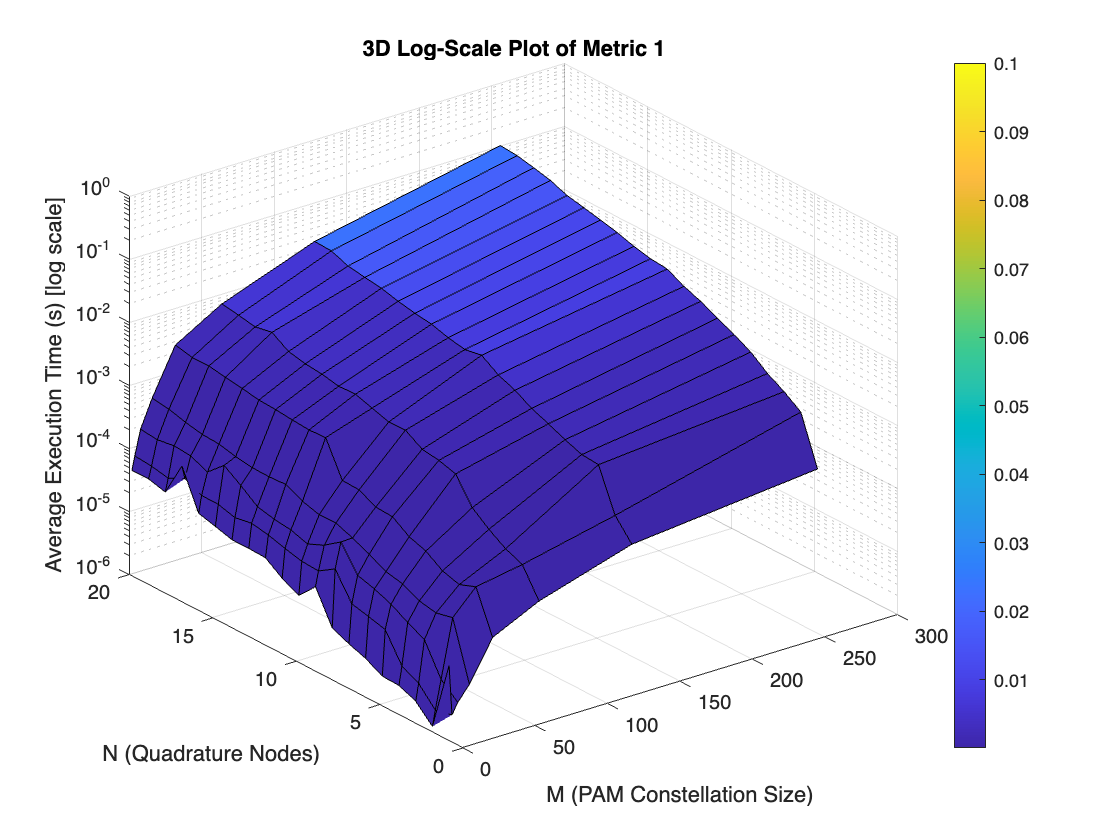

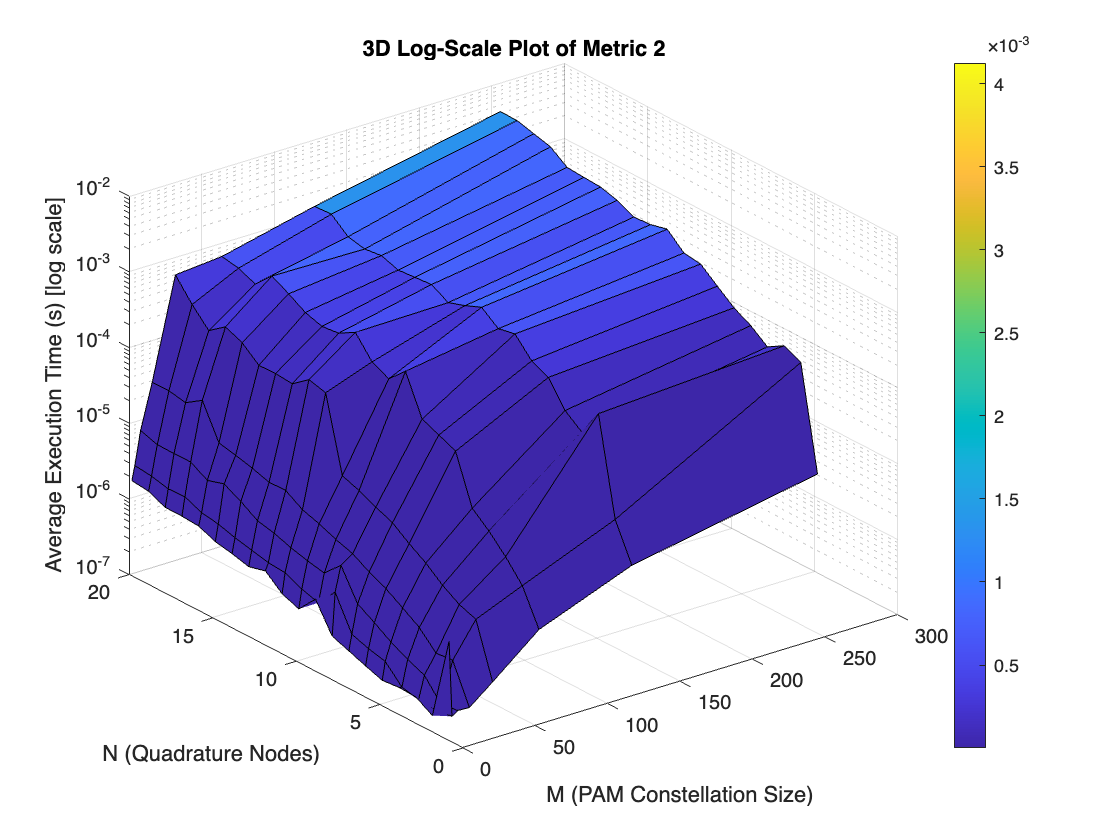

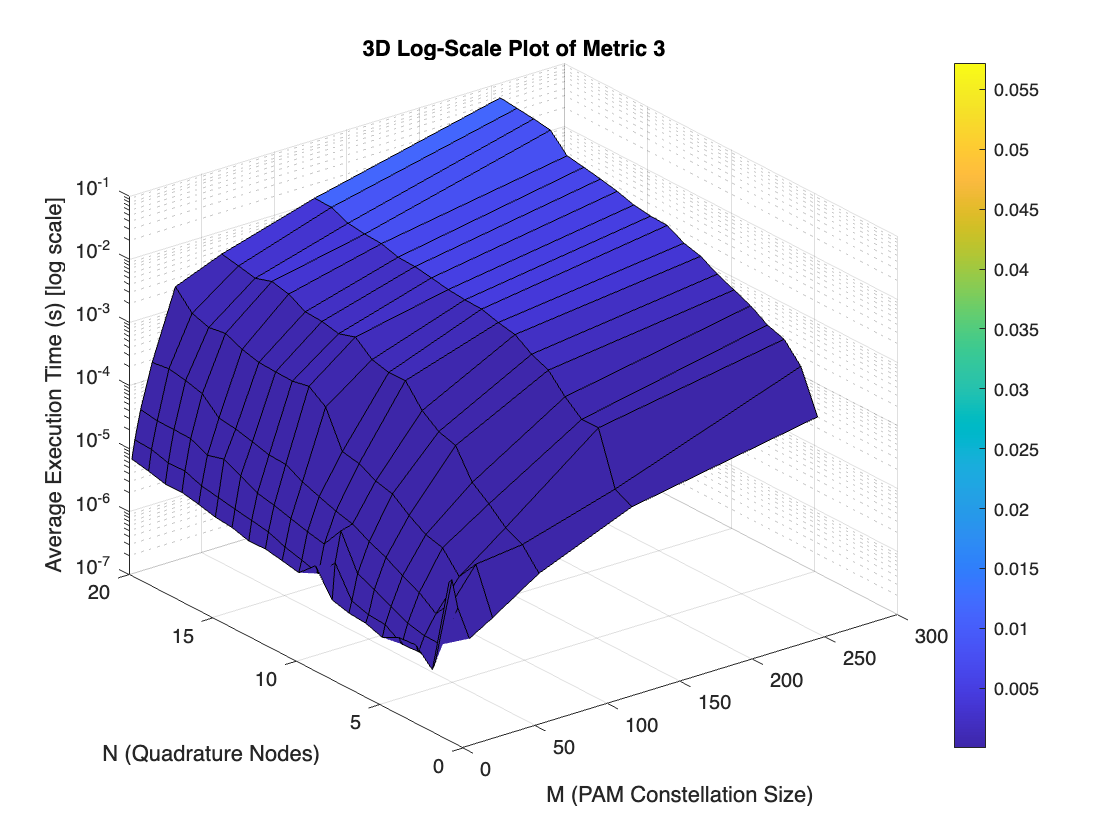

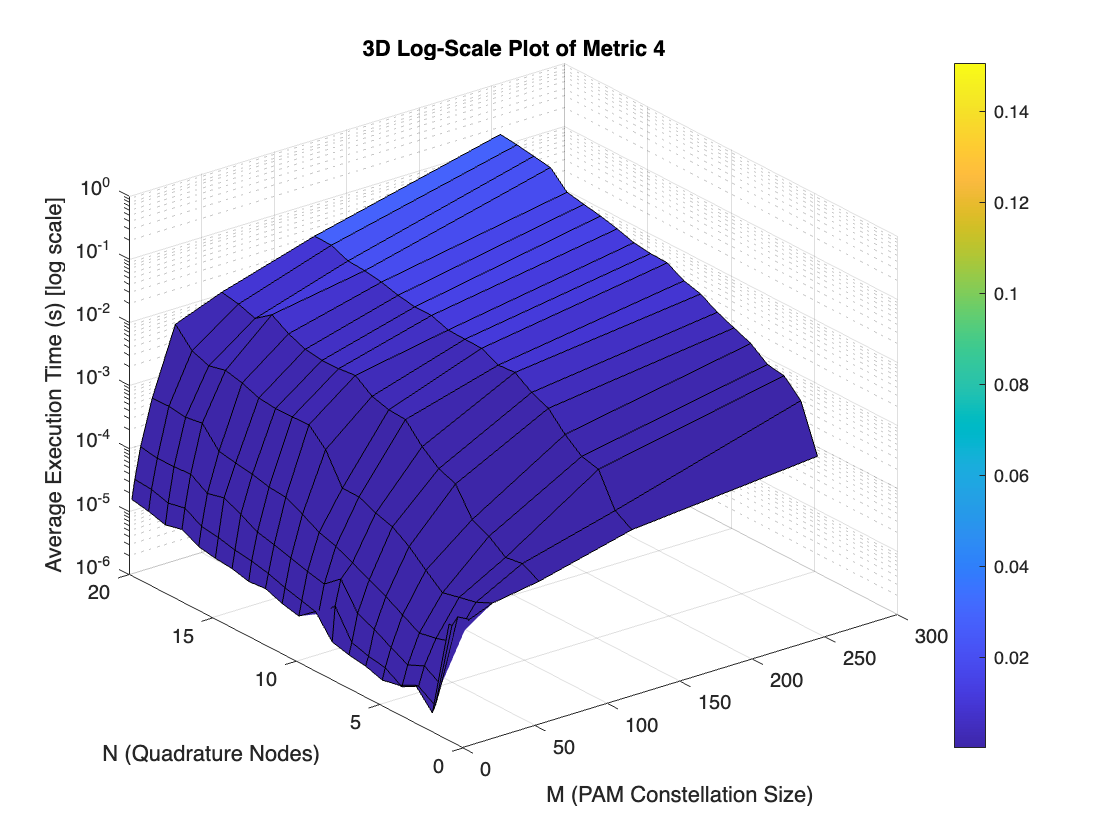

% %% System Parameters
% Nset = 1:20;                                   % Quadrature nodes: 1, 2, ..., 20
% M_array = [2, 4, 8, 16, 32, 64, 128, 256];  % PAM constellation sizes from 2 up to 1024
% SNR = 1;                                       % Signal-to-Noise Ratio
% d = 2;                                         % Distance parameter (spacing between constellation points)
% R = 0.5;                                       % Communication rate (available if needed)
% 
% %% Preallocate arrays for execution times
% numMetrics = 4;  % We assume 4 timing metrics are returned from your functions
% total_times_old = zeros(numMetrics, length(M_array), length(Nset));
% total_times_new = zeros(numMetrics, length(M_array), length(Nset));
% 
% nIter = 100;  % Number of iterations for averaging execution time
% 
% %% Main Simulation Loop
% for idxN = 1:length(Nset)
%     N = Nset(idxN);
% 
%     % Compute Gauss-Hermite Nodes and Weights for current N.
%     % (Ensure your function handles N=1 gracefully.)
%     [nodes, weights] = GaussHermite_Locations_Weights(N);
% 
%     % Compute the complex nodes matrix once per N (depends only on nodes)
%     z_matrix = createComplexNodesMatrix(nodes);
% 
%     for idxM = 1:length(M_array)
%         M = M_array(idxM);
% 
%         %% Generate and Normalize PAM Constellation
%         X = generatePAMConstellation(M, d);
%         X = X / sqrt(mean(X.^2));  % Normalize constellation to unit average energy
% 
%         %% Initialize the Probability Distribution for Constellation Symbols
%         Q = repmat(1/M, M, 1);  % Uniform probability distribution for each symbol
% 
%         %% Define the Gaussian Function
%         G = @(z) exp(-abs(z).^2) / pi;
% 
%         %% Create Required Matrices for Computation
%         pi_matrix = createPiMatrix(M, N, weights);
%         g_matrix = createGMatrix(X, z_matrix, SNR, G);
% 
%         % Parameter for the integration algorithm
%         rho = 0.5;
%         T_new = zeros(1, numMetrics);
%         T_old = zeros(1, numMetrics);
% 
%         %% Run simulation nIter times to average the execution times
%         for j = 1:nIter
%             % The functions below are assumed to return 4 timing metrics in the 4th output.
%             [~, ~, ~, times_old] = F0_matrix(Q, pi_matrix, g_matrix, rho);
%             [~, ~, ~, times_new] = derivativesE0(Q, pi_matrix, g_matrix, rho);
%             T_new = T_new + times_new;
%             T_old = T_old + times_old;
%         end
% 
%         % Store the average execution times for this combination of M and N
%         total_times_new(:, idxM, idxN) = T_new' / nIter;
%         total_times_old(:, idxM, idxN) = T_old' / nIter;
% 
%         % Progress update for the rad simulation
%         disp(['Completed: M = ', num2str(M), ', N = ', num2str(N)]);
%     end
% end
% 
% %% Display the Execution Time Arrays (if needed)
% disp('Old Method Execution Times:');
% disp(total_times_old);
% disp('New Method Execution Times:');
% disp(total_times_new);

%% Create Meshgrid for Plotting
% X-axis (M) and Y-axis (N)
[M_grid, N_grid] = meshgrid(M_array, Nset);

%% 3D Surface Plots for the 4 Metrics (New Method) in Log Scale
for metric = 1:numMetrics
    % Extract the average execution times for the current metric.
    % squeeze converts from [1 x length(M_array) x length(Nset)] to [length(M_array) x length(Nset)],
    % and then we transpose so that the first dimension corresponds to Nset.
    time_metric = squeeze(total_times_new(metric, :, :))';  
    
    figure;
    surf(M_grid, N_grid, time_metric);
    
    % Set the Z-axis (execution time) to log scale.
    set(gca, 'ZScale', 'log'); 
    
    xlabel('M (PAM Constellation Size)');
    ylabel('N (Quadrature Nodes)');
    zlabel('Average Execution Time (s) [log scale]');
    title(['3D Log-Scale Plot of Metric ', num2str(metric)]);
    colorbar;
end